%Script to graph results from experimental verification 

%Forward kinematic analysis
testCasesFK = [1;2;3;4;5;6;7;8;9;10;11;12;13;14;15;16;17;18;19;20];

testCasesFK =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


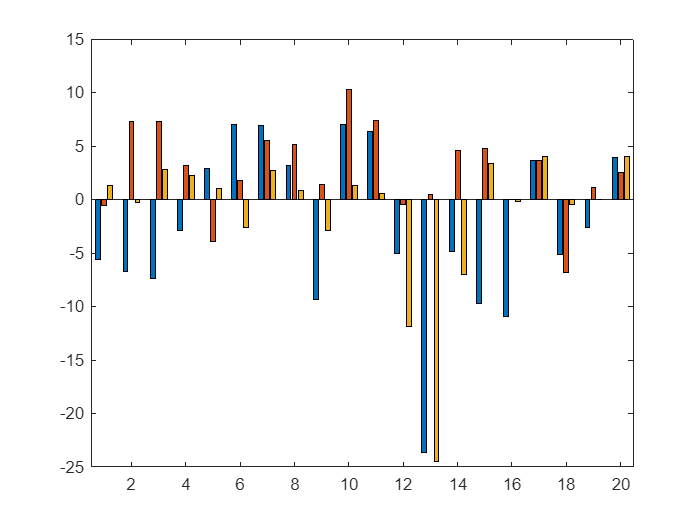

FKgraph =   1×3 Bar array:

    Bar    Bar    Bar


xErrorFK = [-5.6;-6.7;-7.4;-2.9;2.9;7;6.9;3.2;-9.3;7;6.4;-5;-23.6;-4.9;-9.7;-10.9;3.6;-5.1;-2.6;3.9];
yErrorFK = [-0.6;7.25;7.3;3.2;-3.9;1.73;5.5;5.1;1.43;10.3;7.4;-0.5;0.5;4.54;4.8;0;3.6;-6.8;1.1;2.5];
zErrorFK = [1.3;-0.3;2.8;2.2;1;-2.6;2.7;0.85;-2.9;1.3;0.6;-11.9;-24.5;-7;3.4;-0.2;4;-0.5;0;4];
bargraphFK = zeros([20,3]);

for i=1:20
    bargraphFK(i,1) = xErrorFK(i);
    bargraphFK(i,2) = yErrorFK(i);
    bargraphFK(i,3) = zErrorFK(i);
end

FKgraph = bar(testCasesFK,bargraph)

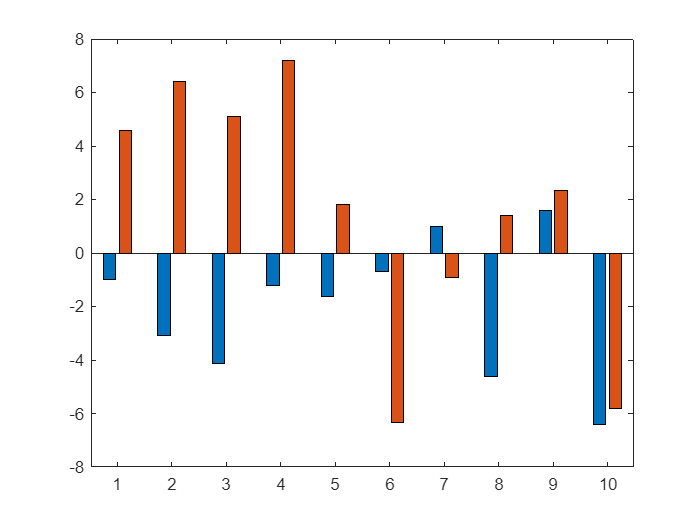

IKgraph =   1×2 Bar array:

    Bar    Bar



%Inverse kinematic analysis
testCasesIK = [1,2,3,4,5,6,7,8,9,10];
theta_2Error = [-0.99;-3.07;-4.12;-1.2;-1.64;-0.7;0.98;-4.6;1.6;-6.4];
theta_3Error = [4.58;6.4;5.12;7.2;1.81;-6.34;-0.9;1.4;2.32;-5.8];
bargraphIK = zeros([10,2]);

for j=1:10
    bargraphIK(j,1) = theta_2Error(j);
    bargraphIK(j,2) = theta_3Error(j);
end

IKgraph = bar(testCasesIK,bargraphIK)